clc; clear; close all;


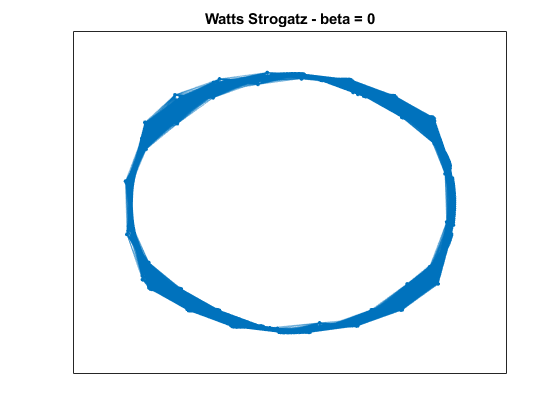

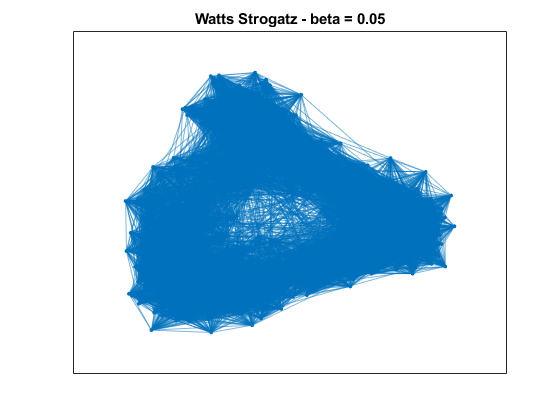

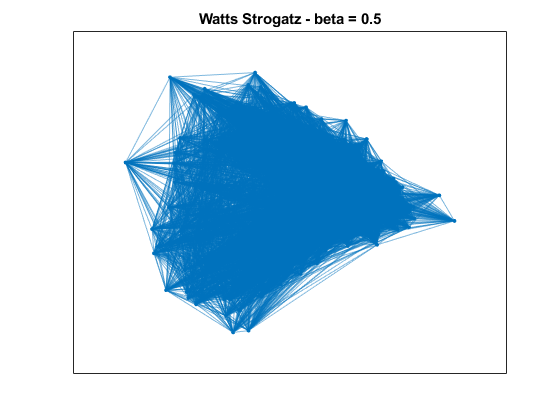

N = 600;
K = 30;
beta = [0, 0.05, 0.5];

for i = 1:length(beta)
    figure(i);
    G = WattsStrogatz(N,K,beta(i));
    p = plot(G);
    title(['Watts Strogatz - beta = ', num2str(beta(i))]);
    deg(i,:) = degree(G);
end

meanDeg = mean(deg, 2)

meanDeg =     60
    60
    60


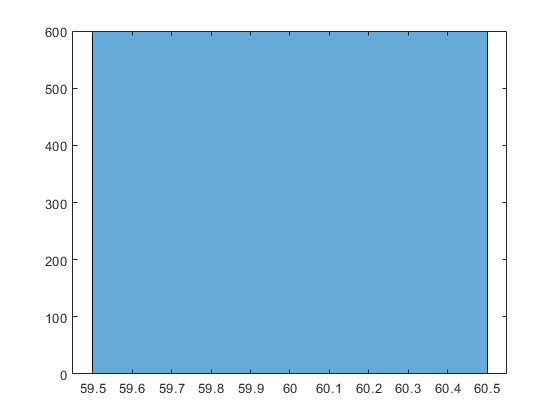

%degree distribution for beta = 0
histogram(deg(1,:));

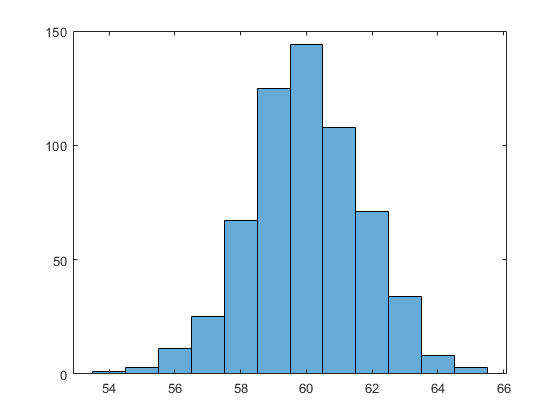

%degree distribution for beta = 0.05
histogram(deg(2,:));

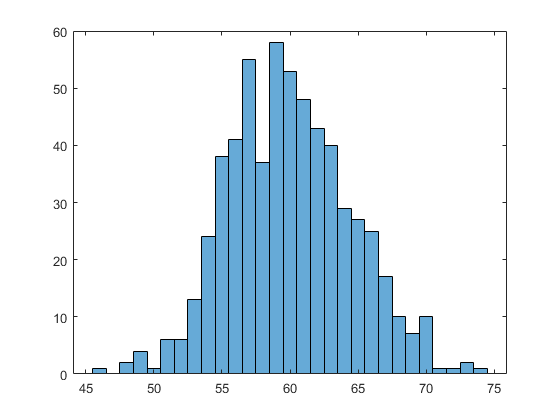

%degree distribution for beta = 0.5
histogram(deg(3,:));

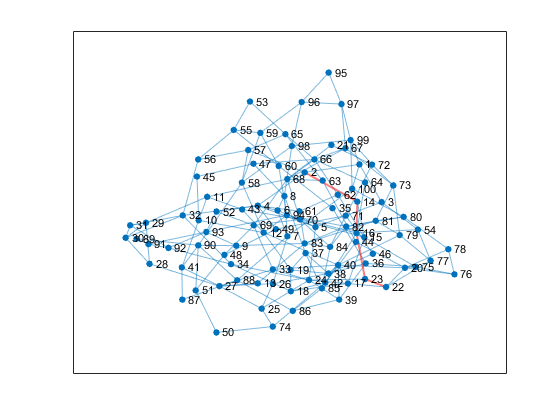

The path is given by
    22    23    16    14     2

The length of the path is 4.


%Myopic Search
A = load('data.mat');
myopic(22, 2, A.A);

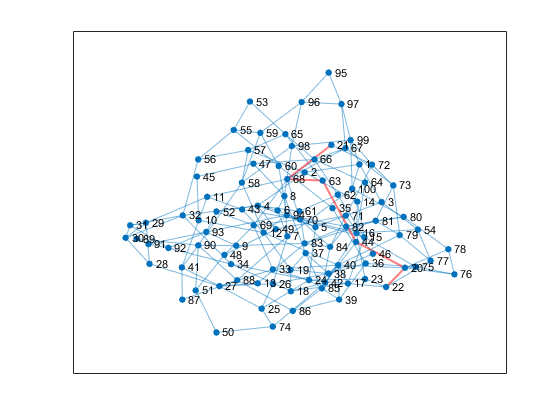

The path is given by
    22    20    44    63    68    21

The length of the path is 5.


myopic(22, 21, A.A);

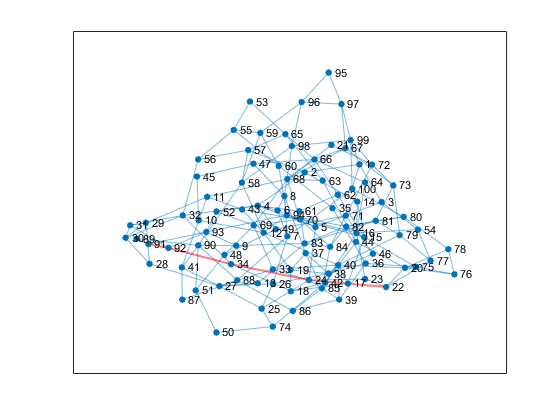

The path is given by
    22    24    34    92    91

The length of the path is 4.


myopic(22, 91, A.A);

%compare myopic with shortestpath
Gd = graph(A.A);
pathGd = shortestpath(Gd, 22, 2)

pathGd =     22    23    16    14     2


lengthPathGd = length(pathGd) - 1

lengthPathGd = 4